# Honours Live Script 7

## Load Data

if ~exist("workspaceVarHonours", 'var')
    load matlabHonours.mat
    setInterpLatex()
end

## Save Data

if exist("workspaceVarHonours", 'var')
    clearVarsArray = clearVars();
    clear(clearVarsArray{:})
    clear clearVarsArray
    save matlabHonours.mat
end 

% set the default intepreter to latex
setInterpLatex()

## Contents

Stochastic Two Population Model

Clumped-ness Metric Code

Connected Reefs Hypothesis - Townsville Region

Connected Reefs Hypothesis - Southern Region

Connected Reefs Hypothesis - Swains Region

Clumped-ness Metric Code

Comparing MPA Characteristics Figure

Connectivity Matrix Example Figure

Three Reef Analytical Approach Figure

Beverton-Holt Form Figure

Final Experiment Coding

Rezoning - Swains Section

Rezoning - Townsville Section

## Assumptions Made

% note that in this live script, I'm changing the regions I'm looking at to
% both expand them and reposition one

% many of the old location based reef stuff was suffixed by CT, maybe for
% the new structures etc I just drop the CT

% note that I have altered some of the methods which appear in this live
% script, so that if re-run errors will probably be encountered sorry xd :P

## Stochastic Two Population Model

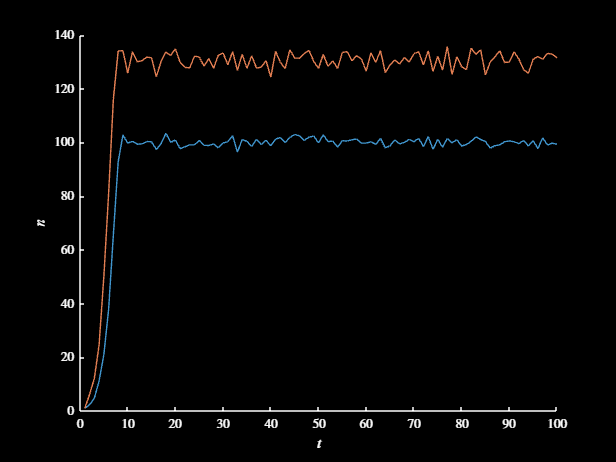

% want to create some simulations of Mike's stochastic two population model
% gonna start with a discrete time version, just because I don't quite
% know how to numerically solve the DE version

% set parameters
r1 = 1.1;
r2 = 1.125;
k1 = 100;
k2 = 130;
sigma1 = 1.5;
sigma2 = 4;
sigmaC = 2;
n1t0 = 1;
n2t0 = 1;
tMax = 100;

% initialise variables
n1Vec = zeros(1, tMax);
n2Vec = zeros(1, tMax);
n1Vec(1) = n1t0;
n2Vec(1) = n2t0;

% loop through time
for t = 2:tMax

    % simulate noise variables
    var1 = unifrnd(-1, 1, 1, 3);

    % calculate populations at next timestep
    n1Vec(t) = (1 + r1 * (1 - n1Vec(t-1) / k1)) * n1Vec(t-1) ...
        + sigma1 * var1(1) + sigmaC * var1(3);
    n2Vec(t) = (1 + r2 * (1 - n2Vec(t-1) / k2)) * n2Vec(t-1)...
        + sigma2 * var1(2) + sigmaC * var1(3);

end

% plot results
figure
hold on
plot(n1Vec)
plot(n2Vec)
xlabel("$t$")
ylabel("$n$")
darkFig()

% let's calculate some descriptive statistics for the system after 20
% timesteps
mean1 = mean(n1Vec(20:end))

mean1 = 99.7543

mean2 = mean(n2Vec(20:end))

mean2 = 129.6587

variance1 = var(n1Vec(20:end))

variance1 = 5.3814

variance2 = var(n2Vec(20:end))

variance2 = 9.6345


% the means match the carrying capacity as expected, but do the variances
% match Mike's predictions?
variance1Calc = k1 * (sigma1^2 + sigmaC^2) / (2 * r1)

variance1Calc = 738.6364

variance2Calc = k2 * (sigma2^2 + sigmaC^2) / (2 * r2)

variance2Calc = 1.6391e+03


% not sure this is an entirely accurate comparison however, given that this
% is a discrete time model vs a diff eq model

% wait - I found a solution, although I'm not entirely sure that it will
% work if there are variable timesteps

## Connected Reefs Hypothesis - Townsville Region

% before I go any further, let's calculate some average connectivity
% matrices

% start with Townsville
aveConMatCTTowns = zeros(size(conMatsCTTowns{1}));
for i = 1:nMatsCT
    aveConMatCTTowns = aveConMatCTTowns + conMatsCTTowns{i};
end
aveConMatCTTowns = aveConMatCTTowns / nMatsCT;

% next do the Southern region
aveConMatCTSouth = zeros(size(conMatsCTSouth{1}));
for i = 1:nMatsCT
    aveConMatCTSouth = aveConMatCTSouth + conMatsCTSouth{i};
end
aveConMatCTSouth = aveConMatCTSouth / nMatsCT;

% next do the Swains region
aveConMatCTSwains = zeros(size(conMatsCTSwains{1}));
for i = 1:nMatsCT
    aveConMatCTSwains = aveConMatCTSwains + conMatsCTSwains{i};
end
aveConMatCTSwains = aveConMatCTSwains / nMatsCT;

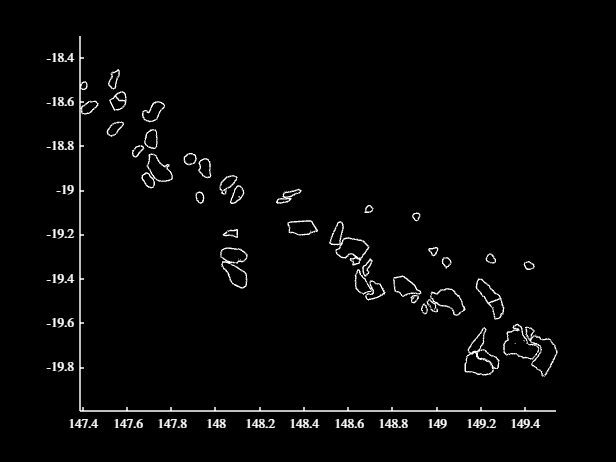

% want to investigate the idea that investing in reefs which are highly
% connected to each other via connectivity might not be optimal

% first, let's plot the region
figure
plotShapeStruct(GBRShapeCTTowns)
darkFig()

% let's now run the simulation, and just do so over the range of
% connectivity matrices
actionStructCT = actionStruct;
[pairedConSimResCTTowns, conStrengthMatCTTowns] = pairedConSim( ...
    conMatsCTTowns, areasCTTowns, popInitCTTowns, specStructCT, ...
    actionStruct);

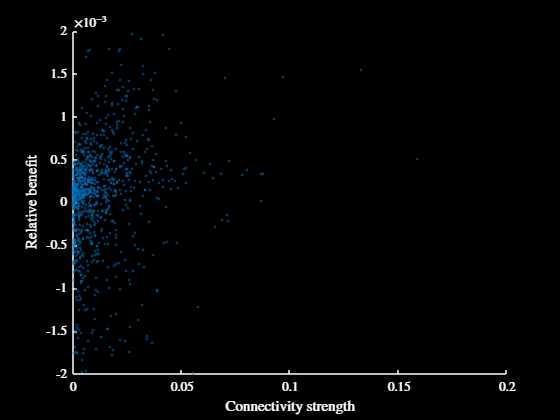

% let's figure out a way to plot these results xd
figure
plotPairedConSim(pairedConSimResCTTowns, conStrengthMatCTTowns)
ylim([-2 * 10^-3, 2 * 10^-3])
xlim([0, 0.2])
darkFig()


% this does not look super informative lmao, so I should go back and check
% over my code lmao - but also I could instead be lazy and just like 

## Connected Reefs Hypothesis - Southern Region

% repeat the same analysis for the southern region
[pairedConSimResCTSouth, conStrengthMatCTSouth] = pairedConSim( ...
    conMatsCTSouth, areasCTSouth, popInitCTSouth, specStructCT, ...
    actionStruct);

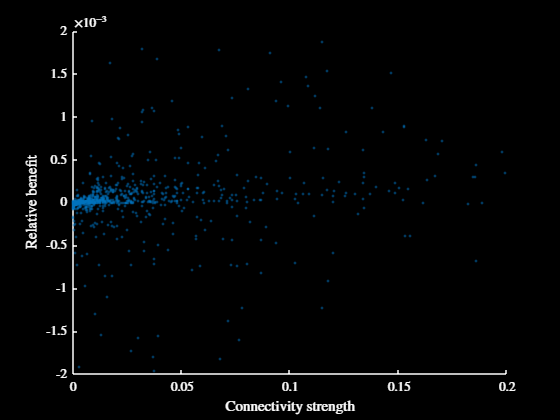

% plot the results
figure
plotPairedConSim(pairedConSimResCTSouth, conStrengthMatCTSouth)
ylim([-2 * 10^-3, 2 * 10^-3])
xlim([0, 0.2])
darkFig()

## Connected Reefs Hypothesis - Swains Region

% repeat the same analysis for the southern region
[pairedConSimResCTSwains, conStrengthMatCTSwains] = pairedConSim( ...
    conMatsCTSwains, areasCTSwains, popInitCTSwains, specStructCT, ...
    actionStruct);

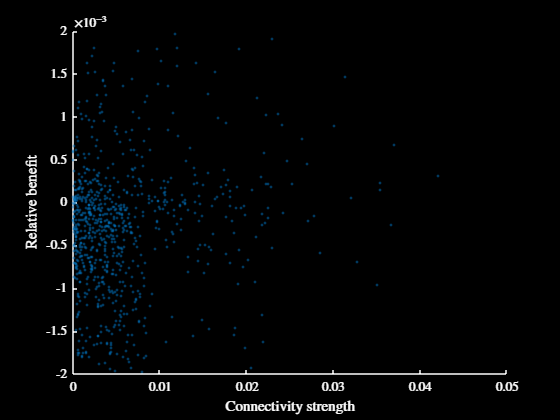

% let's figure out a way to plot these results xd
figure
plotPairedConSim(pairedConSimResCTSwains, conStrengthMatCTSwains)
ylim([-2 * 10^-3, 2 * 10^-3])
xlim([0, 0.05])
darkFig()

% I think I will later try and understand these results better, however for
% the time being, I will go and read that Roughgarden paper methinks

% idk - tbh it doesn't seem like there is much of a difference, although it
% is kind of hard to interpret when we are comparing to the objective
% function across the entire region - maybe we could instead look at just
% the amounts for the two reefs themselves instead - it could maybe be
% possible here that we're seeing minimal changes due to reef size
% differences etc

% look at this once I come back from toiler

## Clumped-ness Metric Code

% gonna write some code where u pass in a vector of the centroids, and
% selected reefs, and you get out a metric of clumped-ness

% for a start, let's just create a random example so I can test the ideas
rng(2)
points = rand(20, 2);
figure
% plot(points(:, 1), points(:, 2), '.', 'MarkerSize', 10)
% for i = 1:length(points)
%     text(points(i, 1), points(i, 2), num2str(i))
% end
% darkFig()

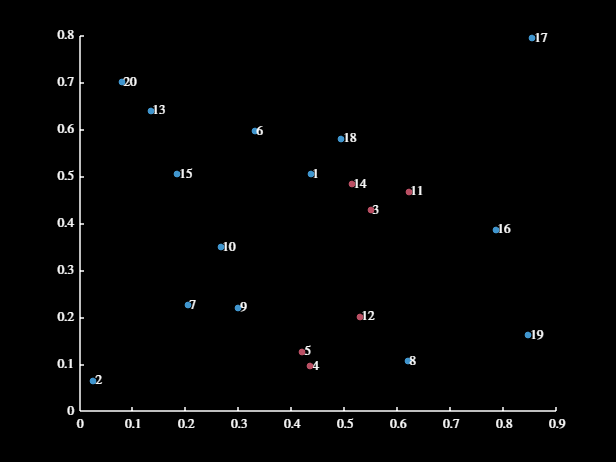

% now, let's choose a subset of these that is going to result in high
% clumpiness, and so will have a low spread
subset1 = zeros(20, 1);
var1 = [4, 5, 12, 14, 3, 11];
subset1(var1) = 1;

% plot those that I've chosen for this first subset
var10 = 15;
figure
hold on
plot(points(:, 1), points(:, 2), '.', 'MarkerSize', var10)
for i = 1:length(points)
    text(points(i, 1), points(i, 2), num2str(i))
    if subset1(i) == 1
        plot(points(i, 1), points(i, 2), '.', 'Color', getColour('r'), ...
            'MarkerSize', var10)
    end
end
darkFig()


% calculate the clumpiness
var3 = calcSpatialSpread(subset1, points)

var3 = 0.0255

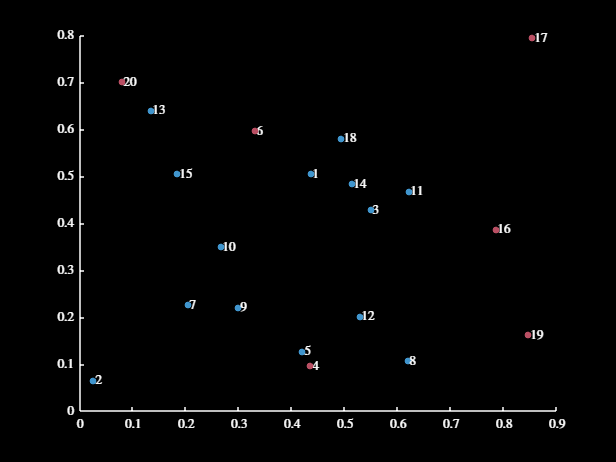

% create a second example, in which the points are more spread out
subset2 = zeros(20, 1);
var1 = [20, 19, 4, 16, 17, 6];
subset2(var1) = 1;

% plot those that I've chosen for this first subset
var10 = 15;
figure
hold on
plot(points(:, 1), points(:, 2), '.', 'MarkerSize', var10)
for i = 1:length(points)
    text(points(i, 1), points(i, 2), num2str(i))
    if subset2(i) == 1
        plot(points(i, 1), points(i, 2), '.', 'Color', getColour('r'), ...
            'MarkerSize', var10)
    end
end
darkFig()


% calculate the clumpiness
var3 = calcSpatialSpread(subset2, points)

var3 = 0.0895

% this seems decent, let's do a couple other examples
subset2 = zeros(20, 1);
var1 = [2, 17];
subset2(var1) = 1;
var3 = calcSpatialSpread(subset2, points)

var3 = 0.8280


% let's do an example of them all relatively spread like the first example,
% but with more points selected
subset2 = zeros(20, 1);
var1 = [4, 5, 12, 14, 3, 11, 20, 13, 1, 18];
subset2(var1) = 1;
var3 = calcSpatialSpread(subset2, points)

var3 = 0.0269


% the above worked perfectly hell yeah - let's try another, but based on
% the second example
subset2 = zeros(20, 1);
var1 = [4, 5, 12, 14, 3, 11, 20, 13, 1, 18];
subset2(var1) = 1;
var3 = calcSpatialSpread(subset2, points)

var1 = calcSpatialSpread(reefChoices, centroids)

## Comparing MPA Characteristics Figure

% here, I'm gonna start trying to code up the figure that will show all of
% the comparisons

% for a start, here are the things we're gonna plot:

% the number of reefs chosen for each method

% somehow do a distribution of the selection frequencies

% do the measure of clumpy-ness thingy

% the overlap proportions imagesc thingy

modStrings = 1×5 string array
    "$k = 1$"    "$k = 0.75$"    "$k = 0.5$"    "$k = 0.25$"    "$k = 0$"


modStringsPlusRand = [modStrings, "Rand."]

modStringsPlusRand = 1×6 string array
    "$k = 1$"    "$k = 0.75$"    "$k = 0.5$"    "$k = 0.25$"    "$k = 0$"    "Rand."


% yooo - should later change my code for the boxplots to make sure they
% represent the standards for the boxplots, rather than just having them as
% this weird 95% CI that will probably just cause more confusion

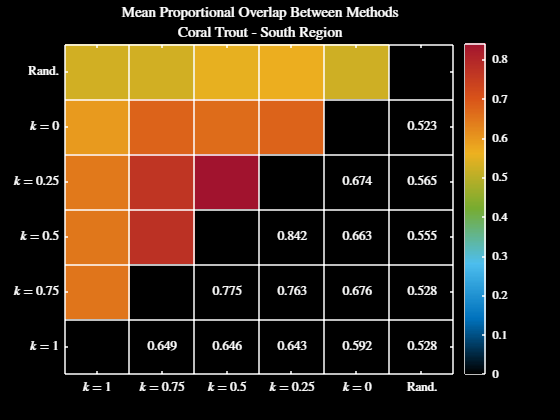

% for a start, we have the good ol' proportional overlap figure
figure
plotOverlapProps(mpaSelCTSouth, 1:6, modStringsPlusRand)
darkFig()
title("Mean Proportional Overlap Between Methods")
subtitle("Coral Trout - South Region")

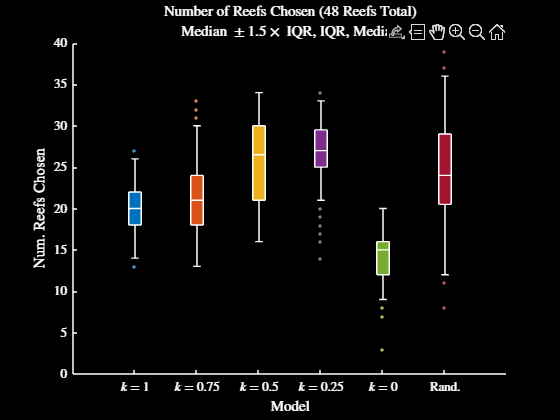

% let's now do a figure for the number of reefs chosen - should be pretty
% simple
figure
plotNumReefsChosen(mpaSelCTSouth, 1:6, modStringsPlusRand)
darkFig()

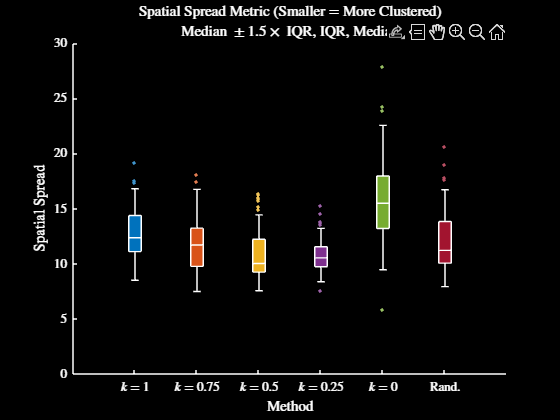

% let's do a figure for the clumpiness
figure
plotSpatialSpread(mpaSelCTSouth, centroidsCTSouth, 1:6, ...
    modStringsPlusRand, true)
ylim([0, 30])
darkFig()

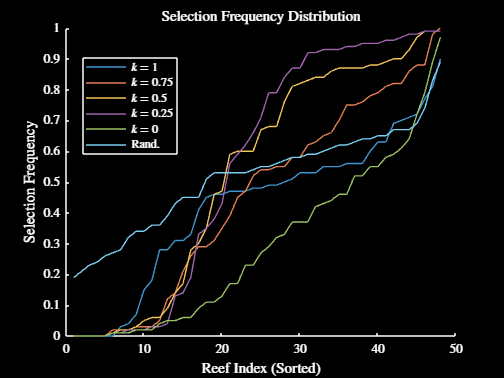

% finally, let's do a figure for the distribution of the selection
% frequencies
figure
plotSelectionFreq(mpaSelCTSouth, 1:6, modStringsPlusRand)
darkFig()

% test my boxplot method
var1 = rand(10, 1);
var1 = [var1; 2; -4];
var2 = rand(10, 1) + 1;
var2 = [var2; 2; -4];
figure
myBoxPlot([var1, var2])
darkFig()

## Connectivity Matrix Example Figure

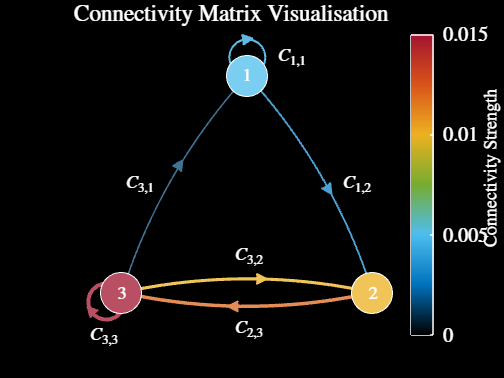

% setup the connectivity matrix
var1 = [0.004, 0.003, 0;
        0, 0, 0.012;
        0.0015, 0.01, 0.015];

% visualise that mf
figure
visualiseConMat(var1)
title("Connectivity Matrix Visualisation")
var2 = colorbar;
text(1.675, -0.2, "Connectivity Strength", "Rotation", 90)
var3 = 15;
text(0.2, 1.13, "$C_{1, 1}$")
text(0.65, 0.25, "$C_{1, 2}$")
text(-0.85, 0.25, "$C_{3, 1}$")
text(-0.1, -0.25, "$C_{3, 2}$")
text(-0.1, -0.75, "$C_{2, 3}$")
text(-1.1, -0.8, "$C_{3, 3}$")
setFontSize(16.5)

% save the figure
saveFig("conMatVisExample")

% save a dark mode version of the figure
darkFig()
saveFig("conMatVisExampleDM")

## Three Reef Analytical Approach Figure

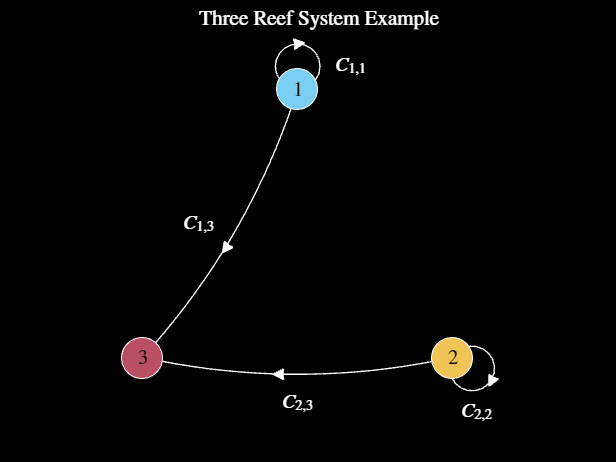

% so that I have a nice little visual for the report, I will do something
% similar to the above, but for three reefs - and remove the colorbar
% methinks
var1 = [0.1, 0, 0.1; 0, 0.1, 0.1; 0, 0, 0];
figure
visualiseConMat(var1, [], "hehe")
title("Three Reef System Example", 'FontSize', 16)
var3 = 15;
text(0.2, 1.13, "$C_{1, 1}$", "FontSize", var3)
text(-0.65, 0.25, "$C_{1, 3}$", "FontSize", var3)
text(0.9, -0.8, "$C_{2, 2}$", "FontSize", var3)
text(-0.1, -0.75, "$C_{2, 3}$", "FontSize", var3)
saveFig("threeReefAnalytical")

% save a dark mode version of the figure
darkFig()
saveFig("threeReefAnalyticalDM")

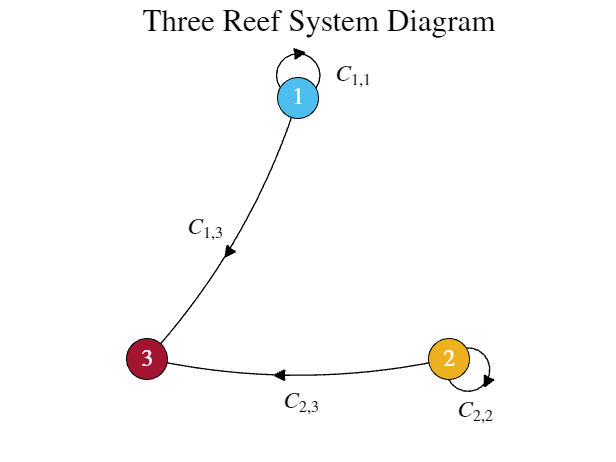

% do it again for the powerpoint
var1 = [0.1, 0, 0.1; 0, 0.1, 0.1; 0, 0, 0];
figure
visualiseConMat(var1, [], "hehe")
title("Three Reef System Diagram")
text(0.2, 1.13, "$C_{1, 1}$")
text(-0.65, 0.25, "$C_{1, 3}$")
text(0.9, -0.8, "$C_{2, 2}$")
text(-0.1, -0.75, "$C_{2, 3}$")
setFontSize(22)
saveFig("threeReefAnalyticalPP")

## Beverton-Holt Form Figure

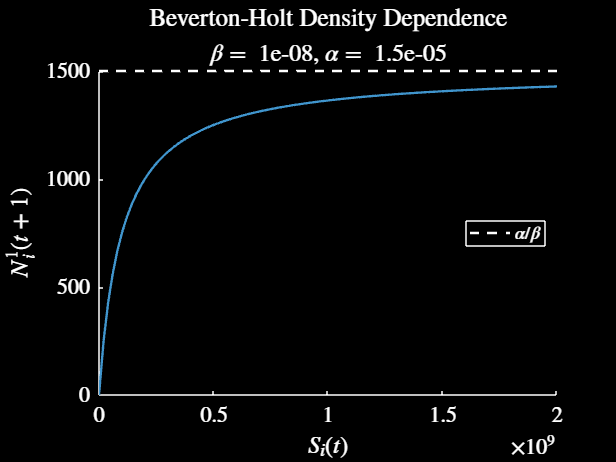

% make a figure here which visualises the form of the Beverton-Holt model
sVec = linspace(0, 2 * 10^9, 100);
alpha = 1.5 * 10^-5;
beta = 10^-8;
recVec = alpha * sVec ./ (1 + beta * sVec);

% plot :O
figure
hold on
plot(sVec, recVec, 'LineWidth', 1.75)
yline(alpha / beta, '--', 'LineWidth', 1.75)
xlabel("$S_i(t)$")
ylabel("$N_i^1(t + 1)$")
title("Beverton-Holt Density Dependence")
subtitle("$\beta = $ " + num2str(beta) + ", $\alpha = $ " ...
    + num2str(alpha))
legend("", "$\alpha / \beta$", 'Location', 'east')
setFontSize(18)

% save the figure in both light and dark mode
saveFig("bevertonHoltVis")
darkFig()
saveFig("bevertonHoltVisDM")

## Final Experiment Coding

% gonna write code here, which can run the final experiments, but
% everything is wrapped in a function, so that I can eventually use
% parfeval and run multiple approaches at a time
runMPASimulation()

var1 = struct with fields:
    test: 1


## Rezoning - Swains Section

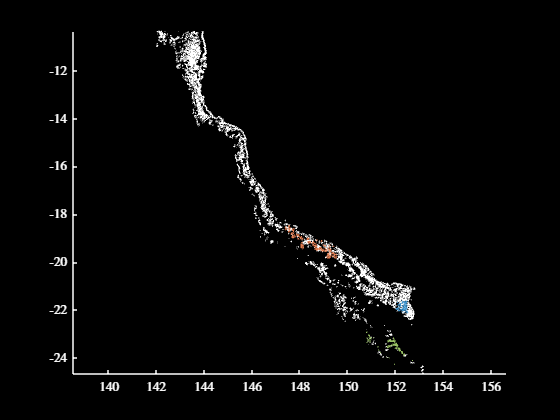

% look at the reef areas
figure
plotShapeStruct(GBRShapeLL)
plotShapeStruct(GBRShapeCTSouth, 'g')
plotShapeStruct(GBRShapeCTSwains, 'b')
plotShapeStruct(GBRShapeCTTowns, 'o')
darkFig()

% note that part of the reason not all reefs in an area are coloured, is
% that not only did I do a little bit of area thresholding, but also the
% connectivity matrices we have don't span every single reef
size(conMatsCT{1})

ans =         1903        1903


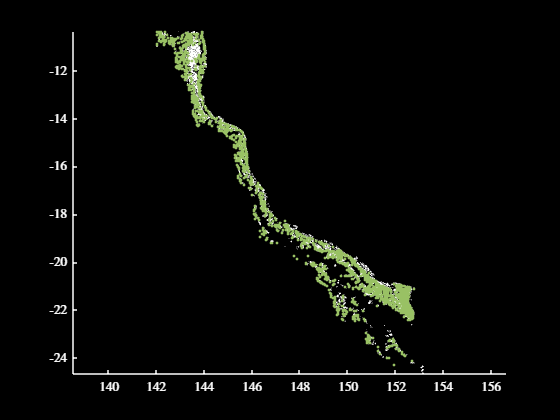


% we can look at this by plotting centroids methinks
figure
plotShapeStruct(GBRShapeLL)
plot(centroidsCT(:, 1), centroidsCT(:, 2), '.', 'Color', ...
    getColour('g'))
darkFig()


% oh shit so the data spans a large length of the GBR, that's pretty
% hectic my goodness

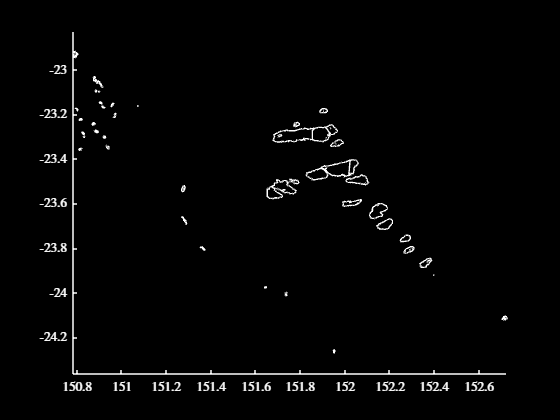

% look at the area in the south south first
figure
plotShapeStruct(GBRShapeCTSouth)
darkFig()


% yeah it's dumb to be looking at this section of the GBR, so I'm going to
% scrap this altogether

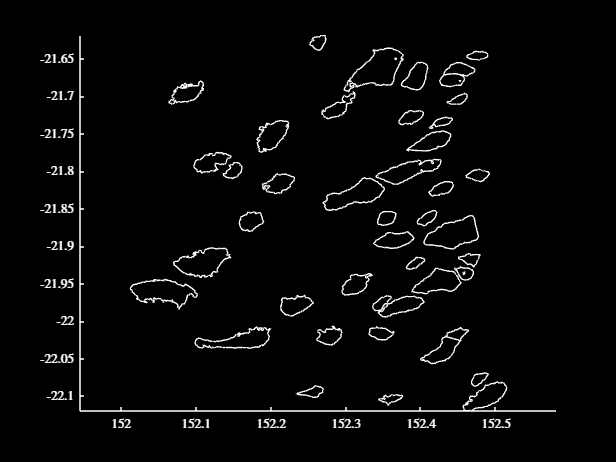

% let's now look at the Swains
figure
plotShapeStruct(GBRShapeCTSwains)
darkFig()

size(conMatsCT{1})

ans =         1903        1903


nReefsCT = length(centroidsCT)

nReefsCT = 1903

% let's go and grab the code that produced this stuff originally, and look
% at extracting more reefs
borderSwains = [151.9, -22; 152.75, -22; 152.75, -21.45; 151.9, -21.45; ...
    151.9, -22];
reefIndsSwains = zeros(nReefsCT, 1);

% find the reefs that fit in with the above border
for i = 1:length(centroidsCT)

    % check if this fits into the border I have defined, along with a
    % minimum area tolerance for computational reasons
    c = centroidsCT(i, :);
    if c(1) > borderSwains(1, 1) && c(1) < borderSwains(2, 1) ...
            && c(2) > borderSwains(1, 2) && c(2) < borderSwains(3, 2) ...
            && areasCT(i) > 0.92 * 10^-4
        reefIndsSwains(i) = 1;
    end

end
reefIndsSwains = reefIndsSwains > 0;
sum(reefIndsSwains)

ans = 100

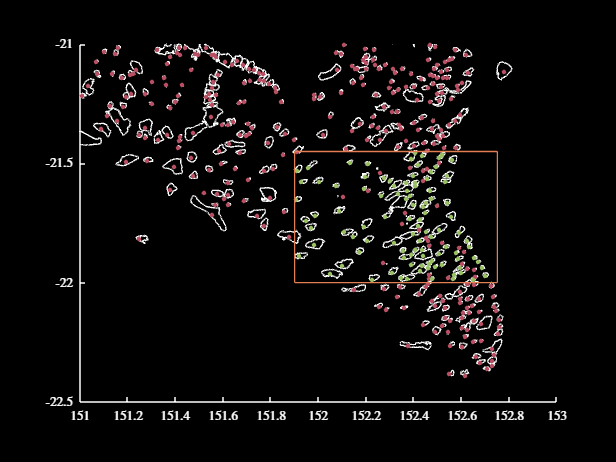

% plot the results
figure
var1 = [151, 153, -22.5, -21];
plotShapeStruct(GBRShapeCT, [], [], [], [], var1)
plot(centroidsCT(~reefIndsSwains, 1), centroidsCT(~reefIndsSwains, 2), ...
    '.', 'Color', getColour('r'), 'MarkerSize', 10)
plot(centroidsCT(reefIndsSwains, 1), centroidsCT(reefIndsSwains, 2), ...
    '.', 'Color', getColour('g'), 'MarkerSize', 10)
plot(borderSwains(:, 1), borderSwains(:, 2), '-', 'Color', getColour('o'))
darkFig()

% let's now extract the meaningful information
nReefsSwains= sum(reefIndsSwains);

% those look good, so let's grab out the connectivity matrices and other
% things that I need
conMatsSwains = conMatsCT;
for m = 1:nMatsCT
    conMatsSwains{m} = conMatsCT{m}(reefIndsSwains, reefIndsSwains);
end
areasSwains = areasCT(reefIndsSwains);
GBRShapeSwains = GBRShapeCT(reefIndsSwains);
centroidsSwains = centroidsCT(reefIndsSwains, :);

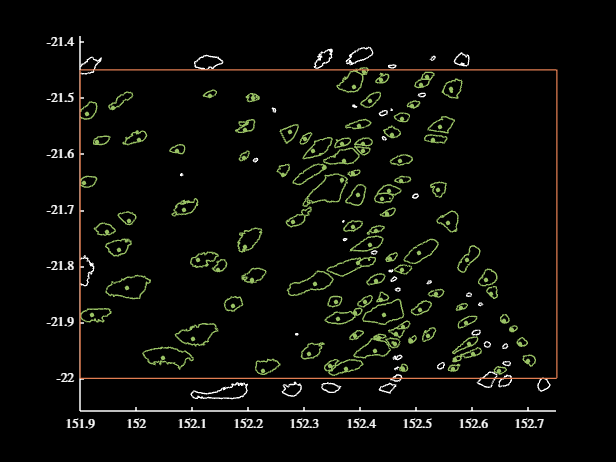

% let's zoom in now closer to the reefs that I have chosen
% plot the results
figure
var1 = [151, 153, -22.5, -21];
plotShapeStruct(GBRShapeCT, [], [], [], [], [borderSwains(1, 1), ...
    borderSwains(2, 1), borderSwains(1, 2), borderSwains(3, 2)])
plotShapeStruct(GBRShapeSwains, 'g')
plot(centroidsCT(reefIndsSwains, 1), centroidsCT(reefIndsSwains, 2), ...
    '.', 'Color', getColour('g'), 'MarkerSize', 10)
plot(borderSwains(:, 1), borderSwains(:, 2), '-', 'Color', getColour('o'))
darkFig()

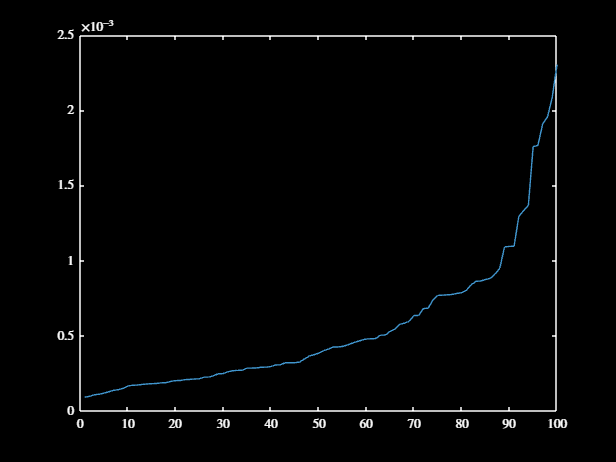

% quickly look at the distribution of areas - might be worthwhile removing
% them for computational reasons
figure
plot(sort(areasSwains))
darkFig()

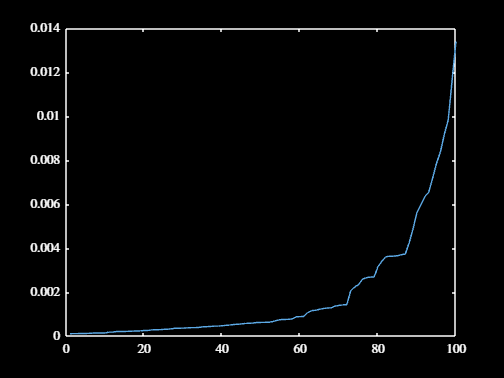

figure
plot(sort(areasTowns))
darkFig()